# Exploring the Experiment's Design

In this set of exercises, we'll get our first look at the experiment we'll be analyzing in this course; curated data from the [Steinmetz et al, 2019](https://www.nature.com/articles/s41586-019-1787-x) paper.

Today's data is focused on three CSV files, each containing sessions  from a different stretch of data collection.  They contain trial-level  data from the experiment:

- steinmetz_winter2016.csv

- steinmetz_summer2017.csv

- steinmetz_winter2017.csv

## Loading and viewing data

Let's load in some csv data with MATLAB and see what we have!

`Download datafiles`

%cwd = fileparts(matlab.desktop.editor.getActiveFilename)
%url= "https://uni-bonn.sciebo.de/s/9FxelLhARmHpw85";
%mkdir(strcat(cwd,'/data'));
%websave(strcat(cwd,'/data/testfile.csv'), strcat(url, '/download') );

**Example: **

Load in the winter 2016 dataset and view the first 5 rows of the data

data = readtable('data/steinmetz_winter2016.csv');
data(1:5,:)

ans = 5×15 table
    trial    active_trials    contrast_left    contrast_right    stim_onset    gocue_time    response_type    response_time    feedback_time    feedback_type    reaction_time    reaction_type     mouse      session_date    session_id
    _____    _____________    _____________    ______________    __________    __________    _____________    _____________    _____________    _____________    _____________    _____________    ________    ____________    __________

    

The variable data is a MATLAB table, we can see that in the Workspace pannel on the right.

**Exercises**

Load in the winter 2016 dataset and view the first 10 rows of the data

data = readtable('data/steinmetz_winter2016_.csv');
data(1:10,:)

ans = 10×16 table
    Var1    trial    active_trials    contrast_left    contrast_right    stim_onset    gocue_time    response_type    response_time    feedback_time    feedback_type    reaction_time    reaction_type     mouse      session_date    session_id
    ____    _____    _____________    _____________    ______________    __________    __________    _____________    _____________    _____________    _____________    _____________    _____________    ________    _______

How many rows are in the summer 2016 dataset?

height(data)

ans = 2747

How many columns are in the summer 2016 dataset?

width(data)

ans = 15

What are the column names in the summer 2016 dataset?

data.Properties.VariableNames

ans = 1×15 cell array
    {'trial'}    {'active_trials'}    {'contrast_left'}    {'contrast_right'}    {'stim_onset'}    {'gocue_time'}    {'response_type'}    {'response_time'}    {'feedback_time'}    {'feedback_type'}    {'reaction_time'}    {'reaction_type'}    {'mouse'}    {'session_date'}    {'session_id'}


## Experiment Description: Calculating Statistics on Continuous Data

**Example**

Find the minimum response time in the table data

min(data.response_time)

ans = 0.5682

**Exercises**

Find the maximum response time in the table data

max(data.response_time)

ans = 2.7136

Find the maximum gocue time in the table data

max(data.gocue_time)

ans = 1.1932

Find the minimum gocue time in the table data

min(data.gocue_time)

ans = 0.4804

Find the mean response time in the table data

mean(data.response_time)

ans = 1.5735

Find the median response_time in the table data

median(data.response_time)

ans = 1.3541

Find the standard deviation of response time

std(data.response_time)

ans = 0.6402

Find the standard deviation of gocue time

std(data.gocue_time)

ans = 0.2011

## Experiment Description: Calculating Statistics of Across Categorical Data

In data  science we often want to perform analysis on distinct separate categories, for example, analysing trials that occured on different days. We can group the data and analyse each group separately, for example finding the mean response time for each mouse.

**Example Exercise**

How many trials occurred for each session date?

groupsummary(data,"session_date")

ans = 9×2 table
    session_date    GroupCount
    ____________    __________

    14-Dec-2016        214    
    17-Dec-2016        251    
    18-Dec-2016        228    
    07-Jan-2017        444    
    08-Jan-2017        412    
    09-Jan-2017        365    
    10-Jan-2017        253    
    11-Jan-2017        142    
    12-Jan-2017        128    


How many trials did each mouse participate in?

groupsummary(data,"mouse")

ans = 3×2 table
       mouse       GroupCount
    ___________    __________

    {'Cori'   }       693    
    {'Muller' }       782    
    {'Radnitz'}       962    


What was the mean response time for each mouse?

groupsummary(data,"mouse", "mean", "response_time")

ans = 3×3 table
       mouse       GroupCount    mean_response_time
    ___________    __________    __________________

    {'Cori'   }       693              1.5909      
    {'Muller' }       782              1.5758      
    {'Radnitz'}       962              1.5591      


What was the minimum response time for each mouse?

groupsummary(data,"mouse", "min", "response_time")

ans = 3×3 table
       mouse       GroupCount    min_response_time
    ___________    __________    _________________

    {'Cori'   }       693             0.56821     
    {'Muller' }       782              0.5854     
    {'Radnitz'}       962             0.58381     


What was the most common (ie. mode) reaction_type for each mouse?

groupsummary(data,"mouse", "mode", "reaction_type")

ans = 3×3 table
       mouse       GroupCount    mode_reaction_type
    ___________    __________    __________________

    {'Cori'   }       693                 1        
    {'Muller' }       782                 1        
    {'Radnitz'}       962                -1        


What was the range of response times for each session date?

groupsummary(data,"session_date", "range", "response_time")

ans = 9×3 table
    session_date    GroupCount    range_response_time
    ____________    __________    ___________________

    14-Dec-2016        214              2.1054       
    17-Dec-2016        251              2.1227       
    18-Dec-2016        228              2.1076       
    07-Jan-2017        444              2.1245       
    08-Jan-2017        412              2.1158       
    09-Jan-2017        365              2.0917       
    10-Jan-2017        253              2.0796       
    11-Jan-2017        142              2.0306       
    12-Jan-2017        128              1.9787       


Rerun the last exercise replaceing "range" with "all"

groupsummary(data,"session_date", "all", "response_time")

ans = 9×14 table
    session_date    GroupCount    mean_response_time    sum_response_time    min_response_time    max_response_time    range_response_time    median_response_time    mode_response_time    var_response_time    std_response_time    nummissing_response_time    nnz_response_time    numunique_response_time
    ____________    __________    __________________    _________________    _________________    _________________    ___________________    ____________________    __________________    _________________    _________________    _________________

## Visualizing the Experimental Design using Plots

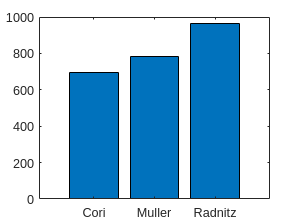

trials_by_mouse = groupsummary(data, "mouse");

bar(trials_by_mouse.mouse, trials_by_mouse.GroupCount)

unique(data.session_date) % Note Matlab autoconverted session_dates to datetime!

ans = 9×1 datetime array
   14-Dec-2016
   17-Dec-2016
   18-Dec-2016
   07-Jan-2017
   08-Jan-2017
   09-Jan-2017
   10-Jan-2017
   11-Jan-2017
   12-Jan-2017



trials_by_date = groupcounts(data,"session_date")

trials_by_date = 9×3 table
    session_date    GroupCount    Percent
    ____________    __________    _______

    14-Dec-2016        214        8.7813 
    17-Dec-2016        251          10.3 
    18-Dec-2016        228        9.3558 
    07-Jan-2017        444        18.219 
    08-Jan-2017        412        16.906 
    09-Jan-2017        365        14.977 
    10-Jan-2017        253        10.382 
    11-Jan-2017        142        5.8268 
    12-Jan-2017        128        5.2524 



histogram('Categories', unique(trials_by_date.day_session_date ),'BinCounts', trials_by_date.GroupCount)

Error using  . 
Unrecognized table variable name 'day_session_date'.

ylabel('num. trials')


bar( unique(trials_by_date.day_session_date ), trials_by_date.GroupCount)

Error using  . 
Unrecognized table variable name 'day_session_date'.